# Check Energy Spectra

## Input h5 Files

fileNameStr = 'C:\Users\nithin\Downloads\20080326.001_bc_15se-energyFlux.h5';
fileNameStr0 = 'G:\My Drive\Research\Projects\Paper 2\Data\Event 1\20080326.001_bc_15sec-fitcal.h5';

## Loading data

data.energyFlux = permute(h5read(fileNameStr,'/energyFluxFromMaxEnt/energyFlux'),[3 2 1]); % in [m^-3]
data.qInput = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInput'); % Need to fix this order
data.qInverted = h5read(fileNameStr,'/energyFluxFromMaxEnt/qInverted');% Need to fix these
data.time = h5read(fileNameStr,'/energyFluxFromMaxEnt/time')';
data.electronDensity = permute(h5read(fileNameStr,'/inputData/Ne'),[3 2 1]);
data.energyBin = h5read(fileNameStr,'/energyFluxFromMaxEnt/energyBin')';
data.alt = h5read(fileNameStr,'/energyFluxFromMaxEnt/alt')';
amisr = read_amisr(fileNameStr0);
data.magBeamNo = amisr.magBeamNo;
clearvars amisr

## Plotting

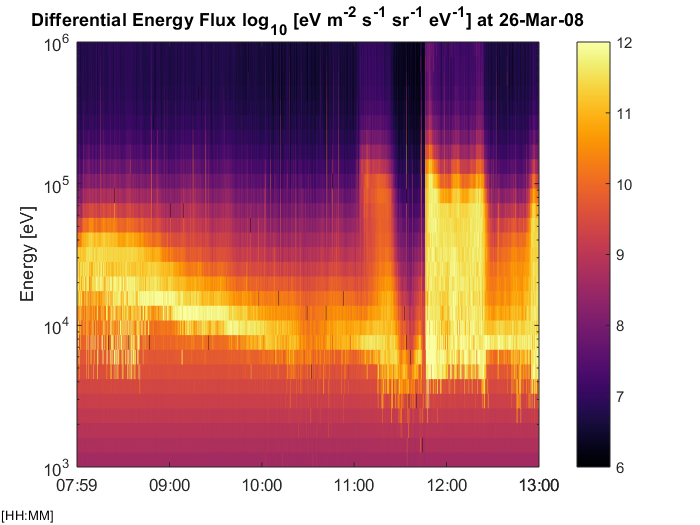

% Time
timeMinStr = '26 Mar 2008 08:00:00';
timeMaxStr = '26 Mar 2008 13:00:00';
figure;
% z = squeeze(data.energyFlux(:,data.magBeamNo,:));
z = squeeze(mean(data.energyFlux,2));
z(z<=0)=10^3;
plot_2D_time_series(data.time',data.energyBin',log10(z)',1,3,timeMinStr,timeMaxStr);
colormap('inferno');
caxis([6 12]);
colorbar;